% incomplete
%Folding property of DTFT
n=50;
M=10;
n=-n:M;
K=500;
tri1=unitseq(min(n),M,0).*(1-(M-1-2*n)/(M-1)); %triangular window functions
x1=tri1

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[Xs,ws]=dtft(x1,n,K);
[x2,n2]=sigfold(x1,n)

x2 =     2.2222    2.0000    1.7778    1.5556    1.3333    1.1111    0.8889    0.6667    0.4444    0.2222         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


n2 =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


[x,nf]=sigmult(x1,n,x2,n2)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


nf =    -50   -49   -48   -47   -46   -45   -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


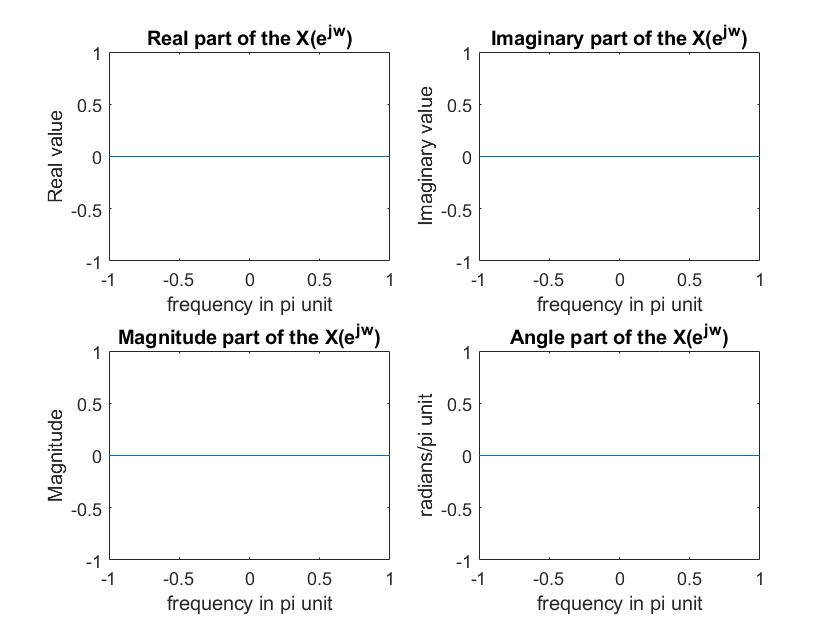

[X,wt]=dtft(x,nf,K);

figure("Name",'j')
dfp4(X,wt)

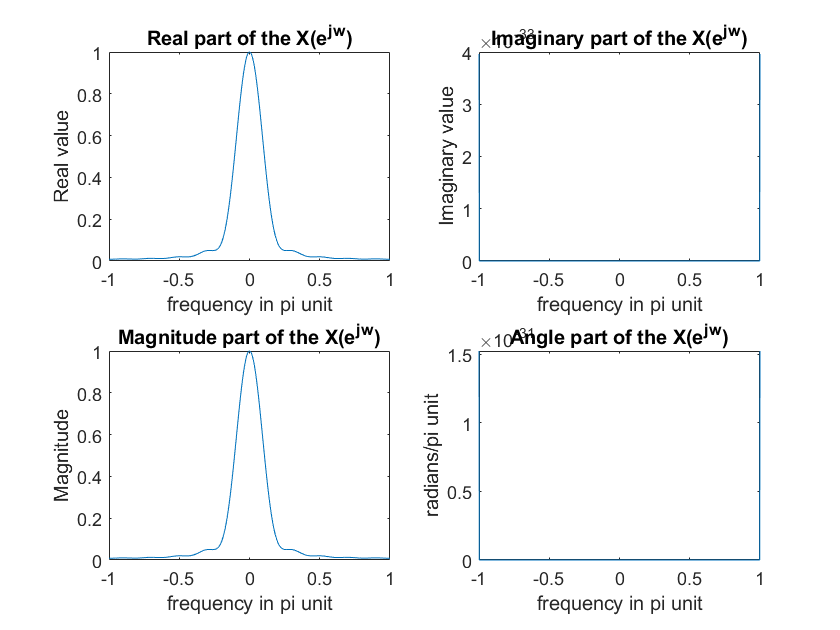


% frequency domain

[X1,w1]=dtft(tri1,n,K);
X2=fliplr(X1);
Xf=X1.*X2;
figure("Name",'jj')
dfp4(Xf/max(Xf),w1)


error=max(abs(X-Xf))

error = 149.3827